time_id_hold = cellfun(@(t) find(t>=.2 & t<=.8), obj.TimeWarped, 'UniformOutput', false);

traj_table = cell(1,2);
traj_table_norm = cell(1,2);
time_hold = cell(1,2);
time_in = cell(1,2);
time_out = cell(1,2);
for j = 1:2
    id = find(obj.HD>0.5 & obj.PortCorrect==obj.Ports(j) & obj.Cued==0);

    t_hold = cellfun(@(t, t_id) t(t_id), obj.TimeWarped(id), time_id_hold(id), 'UniformOutput', false);
    t_hold = cell2mat(t_hold');
    time_hold{j} = t_hold;

    t_in = cellfun(@(t, t_id) t(t_id), obj.TimeFromIn(id), time_id_hold(id), 'UniformOutput', false);
    t_in = cell2mat(t_in');
    time_in{j} = t_in;

    t_out = cellfun(@(t, t_id) t(t_id), obj.TimeFromOut(id), time_id_hold(id), 'UniformOutput', false);
    t_out = cell2mat(t_out');
    time_out{j} = t_out; 

    ang_head = cellfun(@(x, t_id) x(t_id), obj.AngleHead(id), time_id_hold(id), 'UniformOutput', false);
    ang_head = cell2mat(ang_head');

    ang_speed_head = cellfun(@(x, t_id) x(t_id), obj.AngSpeedHead(id), time_id_hold(id), 'UniformOutput', false);
    ang_speed_head = cell2mat(ang_speed_head');

    ang_acc_head = cellfun(@(x, t_id) x(t_id), obj.AngAccHead(id), time_id_hold(id), 'UniformOutput', false);
    ang_acc_head = cell2mat(ang_acc_head');

    x_head = cellfun(@(x, t_id) x(t_id), obj.PosXHead(id), time_id_hold(id), 'UniformOutput', false);
    x_head = cell2mat(x_head');

    x_speed_head = cellfun(@(x, t_id) x(t_id), obj.SpeedXHead(id), time_id_hold(id), 'UniformOutput', false);
    x_speed_head = cell2mat(x_speed_head');

    x_acc_head = cellfun(@(x, t_id) x(t_id), obj.AccXHead(id), time_id_hold(id), 'UniformOutput', false);
    x_acc_head = cell2mat(x_acc_head');

    y_head = cellfun(@(x, t_id) x(t_id), obj.PosYHead(id), time_id_hold(id), 'UniformOutput', false);
    y_head = cell2mat(y_head');

    y_speed_head = cellfun(@(x, t_id) x(t_id), obj.SpeedYHead(id), time_id_hold(id), 'UniformOutput', false);
    y_speed_head = cell2mat(y_speed_head');

    y_acc_head = cellfun(@(x, t_id) x(t_id), obj.AccYHead(id), time_id_hold(id), 'UniformOutput', false);
    y_acc_head = cell2mat(y_acc_head');

    traj_table{j} = table(ang_head, ang_speed_head, ang_acc_head, x_head, x_speed_head, x_acc_head, y_head, y_speed_head, y_acc_head);
    
    traj_table_norm{j} = normalize(traj_table{j}, "range");
end



[coeff,score,latent,tsquared,explained,mu] = pca(table2array(traj_table_norm{2}));

n_dim = find(cumsum(explained)/sum(explained)>0.9, 1);

id_train = randperm(length(time_hold{2}), floor(0.8*length(time_hold{2})));
id_test = setdiff(1:length(time_hold{2}), id_train);


% 
% x = lscov([ones(length(id_train), 1) score(id_train, 1:n_dim)], time_hold{2}(id_train));
% time_pred = [ones(length(id_test), 1) score(id_test, 1:n_dim)] * x;
% 
% figure();
% scatter(time_hold{2}(id_test), time_pred);
% xlim([0 1]); ylim([0 1]); axis square
% 

% x = lscov([ones(length(id_train), 1) score(id_train, 1:n_dim)], time_in{1}(id_train));
% time_pred = [ones(length(id_test), 1) score(id_test, 1:n_dim)] * x;
% 
% figure();
% scatter(time_in{1}(id_test), time_pred);
% xlim([0 1400]); ylim([0 1400]); axis square
% 

% x = lscov([ones(length(id_train), 1) score(id_train, 1:n_dim)], time_out{1}(id_train));
% time_pred = [ones(length(id_test), 1) score(id_test, 1:n_dim)] * x;
% 
% figure();
% scatter(time_out{1}(id_test), time_pred);
% xlim([-1400 0]); ylim([-1400 0]); axis square
% 

% Mdl = fitrsvm(score(id_train, 1:n_dim), time_hold{1}(id_train));
% 
% time_pred = Mdl.predict(score(id_test, 1:n_dim));
% figure();
% scatter(time_hold{1}(id_test), time_pred);
% xlim([0 1]); ylim([0 1]); axis square
% 

% pred_mat = histcounts2(time_hold{1}(id_test), time_pred, 0:0.02:1, 0:0.02:1);
% figure(); colormap('parula')
% imagesc(pred_mat); axis square


MdlCV_linear = fitrlinear(score(:, 1:n_dim), time_hold{2}, 'KFold', 10);
kfoldLoss(MdlCV_linear, "LossFun", @(y, y_fit, ~) 1 - sum((y-y_fit).^2) / sum((y-mean(y)).^2), "Mode", "individual")

ans =     0.2355
    0.2960
    0.3166
    0.1511
    0.3405
    0.1706
    0.2167
    0.2431
    0.2554
    0.2717


kfoldLoss(MdlCV_linear, "LossFun", @(y, y_fit, ~) 1 - var(y-y_fit) / var(y), "Mode", "individual")

ans =     0.2378
    0.2960
    0.3167
    0.1601
    0.3479
    0.1758
    0.2188
    0.2779
    0.2714
    0.2763


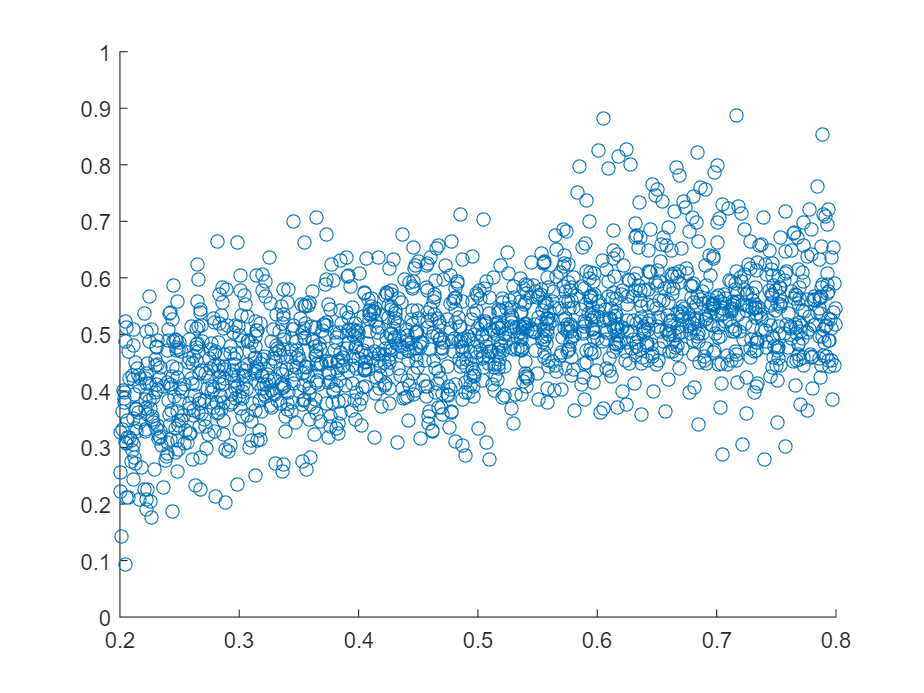


y_fit = kfoldPredict(MdlCV_linear);

figure(); scatter(MdlCV_linear.Y, y_fit); ylim([0 1])

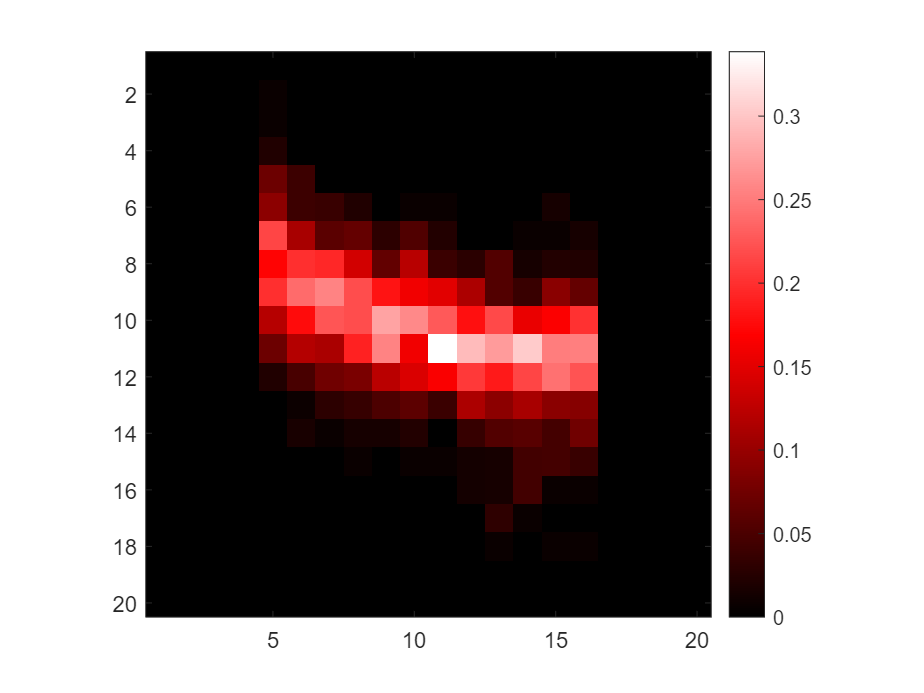


pred_mat = histcounts2(MdlCV_linear.Y, y_fit, 0:0.05:1, -0:0.05:1);
pred_mat = pred_mat';
pred_mat = pred_mat ./ sum(pred_mat);

mycolormap = customcolormap([0 0.5 1], [1 1 1; 1 0 0; 0 0 0]);
figure(); colormap(mycolormap)
imagesc(pred_mat); axis square
colorbar; % caxis([0 1])

MdlCV_svm = fitrsvm(score(:, 1:n_dim), time_hold{2}, 'KFold', 10);
kfoldLoss(MdlCV_svm, "LossFun", @(y, y_fit, ~) 1 - sum((y-y_fit).^2) / sum((y-mean(y)).^2), "Mode", "individual")

ans =    -0.0511
   -0.0226
   -0.0155
   -0.0152
   -0.0191
   -0.0244
    0.0030
   -0.0293
   -0.0109
   -0.0143


kfoldLoss(MdlCV_svm, "LossFun", @(y, y_fit, ~) 1 - var(y-y_fit) / var(y), "Mode", "individual")

ans =    -0.0237
   -0.0217
   -0.0154
   -0.0103
   -0.0164
   -0.0180
    0.0101
   -0.0274
   -0.0052
   -0.0120


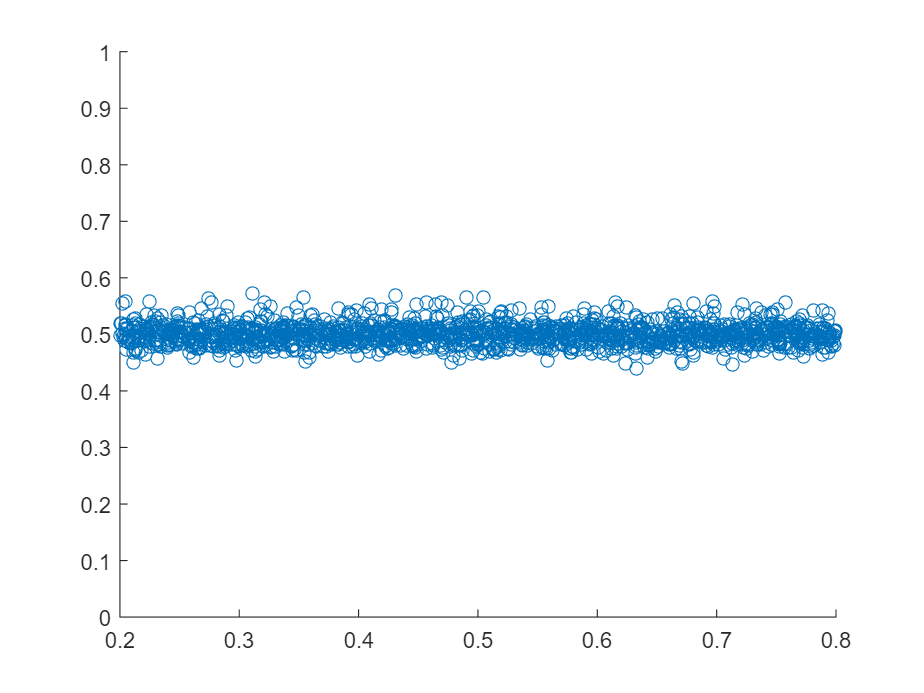


y_fit = kfoldPredict(MdlCV_svm);

figure(); scatter(MdlCV_svm.Y, y_fit); ylim([0 1])

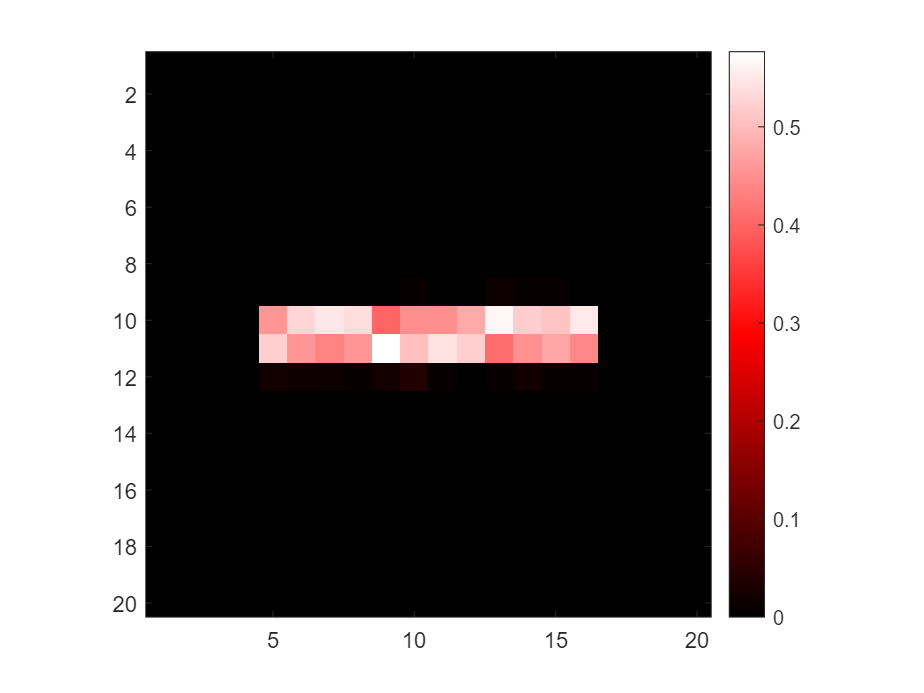


pred_mat = histcounts2(MdlCV_svm.Y, y_fit, 0:0.05:1, -0:0.05:1);
pred_mat = pred_mat';
pred_mat = pred_mat ./ sum(pred_mat);

mycolormap = customcolormap([0 0.5 1], [1 1 1; 1 0 0; 0 0 0]);
figure(); colormap(mycolormap)
imagesc(pred_mat); axis square
colorbar; % caxis([0 1])

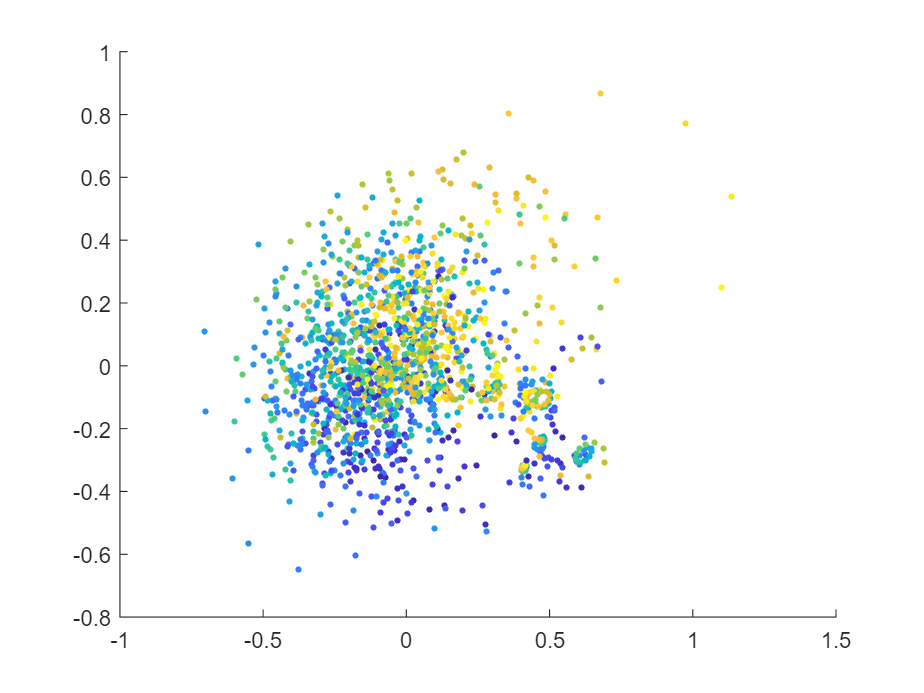

figure();
scatter(score(:,1), score(:,2), 8, time_hold{2}, 'filled')

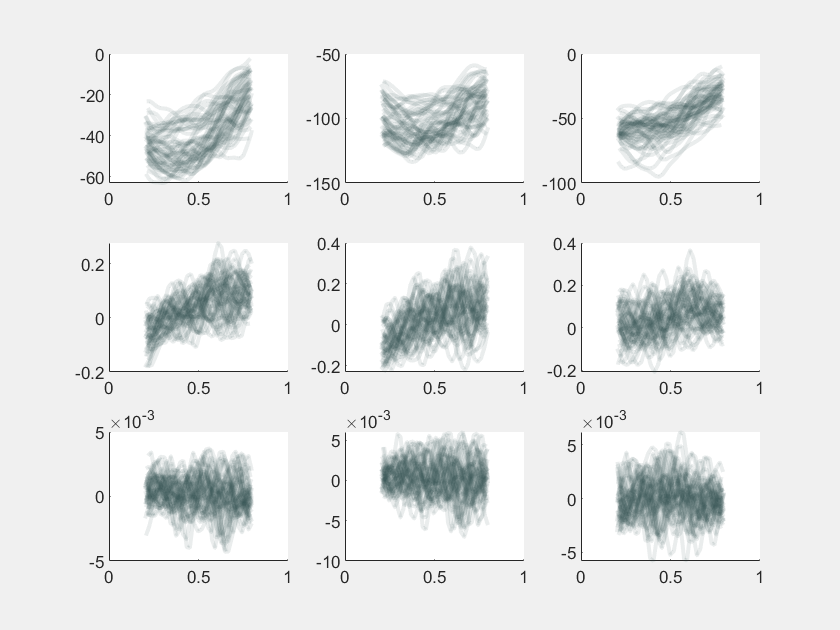

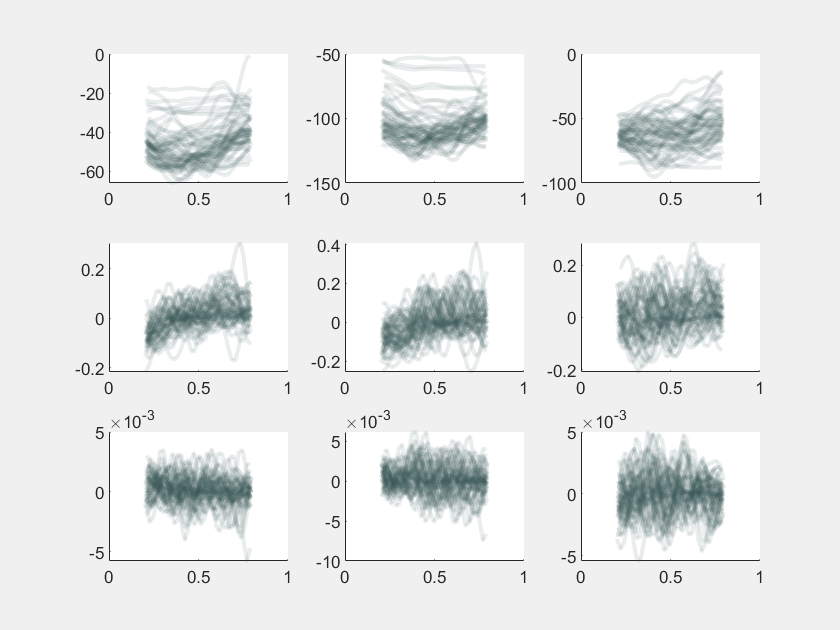

switch obj.Label
    case "Control"
        color_this = GPSColor.Control;
    case "Chemo"
        color_this = GPSColor.Treat;
end

for j = 1:2

    id = find(obj.HD>0.5 & obj.PortCorrect==obj.Ports(j));

    figure('Visible', 'on')

    subplot(3,3,1); hold on
    for i = id
        plot(obj.TimeWarped{i}(time_id_hold{i}), obj.AngleHead{i}(time_id_hold{i}), 'Color', [color_this 0.1], 'LineWidth', 2);
    end
    xlim([0 1]);

    subplot(3,3,2); hold on
    for i = id
        plot(obj.TimeWarped{i}(time_id_hold{i}), obj.PosXHead{i}(time_id_hold{i}), 'Color', [color_this 0.1], 'LineWidth', 2);
    end
    xlim([0 1]);

    subplot(3,3,3); hold on
    for i = id
        plot(obj.TimeWarped{i}(time_id_hold{i}), obj.PosYHead{i}(time_id_hold{i}), 'Color', [color_this 0.1], 'LineWidth', 2);
    end
    xlim([0 1]);

    subplot(3,3,4); hold on
    for i = id
        plot(obj.TimeWarped{i}(time_id_hold{i}), obj.AngSpeedHead{i}(time_id_hold{i}), 'Color', [color_this 0.1], 'LineWidth', 2);
    end
    xlim([0 1]);

    subplot(3,3,5); hold on
    for i = id
        plot(obj.TimeWarped{i}(time_id_hold{i}), obj.SpeedXHead{i}(time_id_hold{i}), 'Color', [color_this 0.1], 'LineWidth', 2);
    end
    xlim([0 1]);

    subplot(3,3,6); hold on
    for i = id
        plot(obj.TimeWarped{i}(time_id_hold{i}), obj.SpeedYHead{i}(time_id_hold{i}), 'Color', [color_this 0.1], 'LineWidth', 2);
    end
    xlim([0 1]);

    subplot(3,3,7); hold on
    for i = id
        plot(obj.TimeWarped{i}(time_id_hold{i}), obj.AngAccHead{i}(time_id_hold{i}), 'Color', [color_this 0.1], 'LineWidth', 2);
    end
    xlim([0 1]);

    subplot(3,3,8); hold on
    for i = id
        plot(obj.TimeWarped{i}(time_id_hold{i}), obj.AccXHead{i}(time_id_hold{i}), 'Color', [color_this 0.1], 'LineWidth', 2);
    end
    xlim([0 1]);

    subplot(3,3,9); hold on
    for i = id
        plot(obj.TimeWarped{i}(time_id_hold{i}), obj.AccYHead{i}(time_id_hold{i}), 'Color', [color_this 0.1], 'LineWidth', 2);
    end
    xlim([0 1]);
end

MdlCV_nn = fitrnet(table2array(traj_table_norm{2}), time_hold{2}, 'LayerSizes', [16 16], 'Activations', 'relu', 'KFold', 10);
kfoldLoss(MdlCV_nn, "LossFun", @(y, y_fit, ~) 1 - sum((y-y_fit).^2) / sum((y-mean(y)).^2), "Mode", "individual")

ans =     0.6306
    0.5796
    0.5725
    0.6014
    0.5664
    0.6171
    0.6504
    0.6219
    0.6412
    0.7075


kfoldLoss(MdlCV_nn, "LossFun", @(y, y_fit, ~) 1 - var(y-y_fit) / var(y), "Mode", "individual")

ans =     0.6326
    0.5797
    0.5727
    0.6020
    0.5701
    0.6206
    0.6506
    0.6235
    0.6432
    0.7088


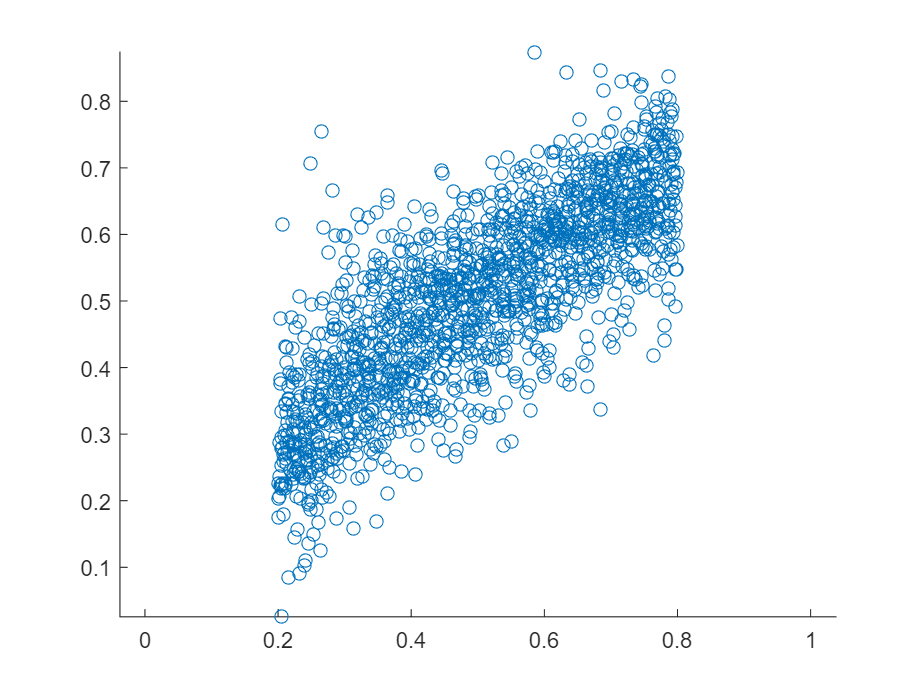


y_fit = kfoldPredict(MdlCV_nn);

figure(); scatter(MdlCV_nn.Y, y_fit); axis equal

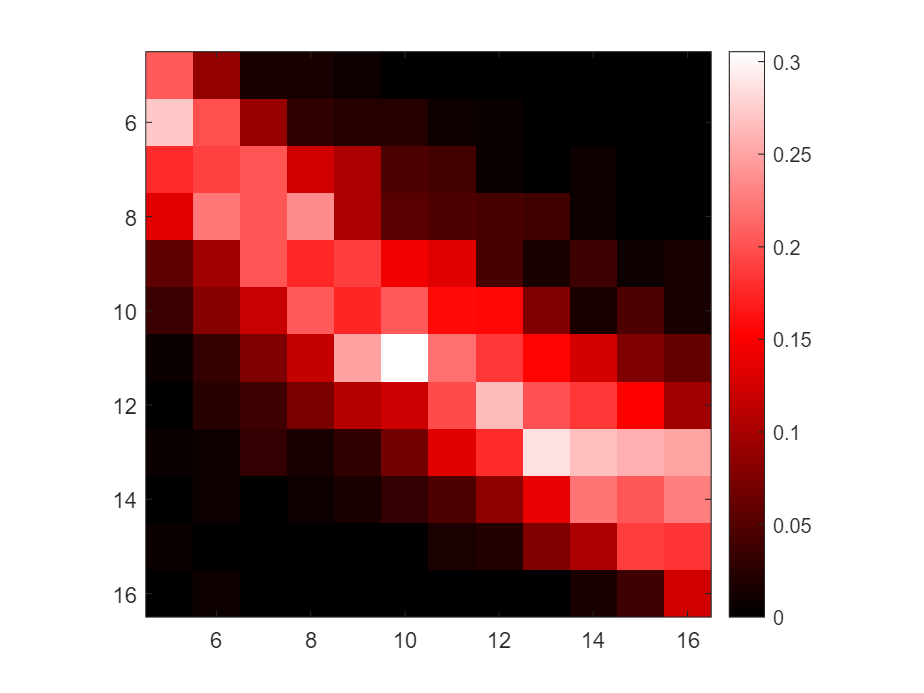


pred_mat = histcounts2(MdlCV_nn.Y, y_fit, 0:0.05:1, -0:0.05:1);
pred_mat = pred_mat';
pred_mat = pred_mat ./ sum(pred_mat);

mycolormap = customcolormap([0 0.5 1], [1 1 1; 1 0 0; 0 0 0]);
figure(); colormap(mycolormap)
imagesc(pred_mat); axis square
xlim([4.5 16.5]); ylim([4.5 16.5])
colorbar; % caxis([0 1])